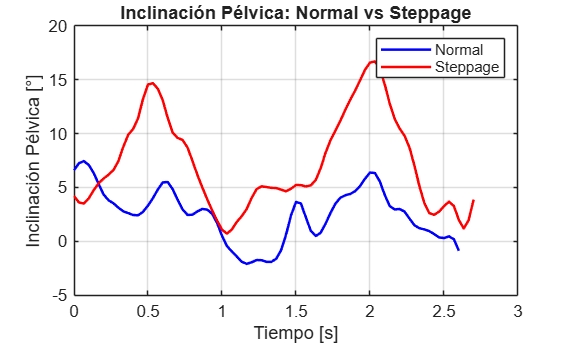

clear;
close all;

%% 1. CARGA Y PREPARACIÓN DE DATOS
% Nombres de las 25 articulaciones (Kinect v2)
jointNames = {'SpineBase', 'MidSpine', 'Neck', 'Head', 'LeftShoulder', ...
    'LeftElbow', 'LeftWrist', 'LeftHand', 'RightShoulder', 'RightElbow', ...
    'RightWrist', 'RightHand', 'LeftHip', 'LeftKnee', 'LeftAnkle', ...
    'LeftFoot', 'RightHip', 'RightKnee', 'RightAnkle', 'RightFoot', ...
    'SpineShoulder', 'LeftHandTip', 'LeftThumb', 'RightHandTip', 'RightThumb'};

% Generar Headers (Time, Joint_X, Joint_Y, Joint_Z...)
varNames = {'Time'}; 
for i = 1:length(jointNames)
    name = jointNames{i};
    varNames{end+1} = [name, '_X'];
    varNames{end+1} = [name, '_Y'];
    varNames{end+1} = [name, '_Z'];
end

% Definir columnas a eliminar (IDs de articulación que no son coordenadas)
colsToDelete = 2:4:101; 

% Cargar Marcha Normal
data_norm = readmatrix('human10_normal1_SkeletonData1.xlsx');
cleanDataNorm = data_norm; 
cleanDataNorm(:, colsToDelete) = []; 
dataTable = array2table(cleanDataNorm, 'VariableNames', varNames);

% Cargar Marcha Steppage
data_step = readmatrix('human1_steppage1_SkeletonData1.csv');
cleanDataStep = data_step; 
cleanDataStep(:, colsToDelete) = []; 
datasteppageTable = array2table(cleanDataStep, 'VariableNames', varNames);

%% 2. ANÁLISIS DE INCLINACIÓN PÉLVICA Y PROCESAMIENTO
% Cálculo de ángulos (Plano XY)
hips_norm = [dataTable.RightHip_X - dataTable.LeftHip_X, dataTable.RightHip_Y - dataTable.LeftHip_Y];
hip_angle_deg = atan2d(hips_norm(:, 2), hips_norm(:, 1));

hips_step = [datasteppageTable.RightHip_X(1:80) - datasteppageTable.LeftHip_X(1:80), ...
             datasteppageTable.RightHip_Y(1:80) - datasteppageTable.LeftHip_Y(1:80)];
hip_angle_step_deg = atan2d(hips_step(:, 2), hips_step(:, 1));

% Remuestreo a 30 Hz (Uniformización)
fs_objetivo = 30;
dt_objetivo = 1 / fs_objetivo;

t_norm_orig = dataTable.Time - dataTable.Time(1);
t_norm_uni = 0 : dt_objetivo : t_norm_orig(end);
hip_norm_uni = interp1(t_norm_orig, hip_angle_deg, t_norm_uni, 'spline');

t_step_orig = datasteppageTable.Time(1:80) - datasteppageTable.Time(1);
t_step_uni = 0 : dt_objetivo : t_step_orig(end);
hip_step_uni = interp1(t_step_orig, hip_angle_step_deg, t_step_uni, 'spline');

% Filtraje Butterworth (Pasa-bajos 6 Hz)
fc = 6;
[b, a] = butter(2, fc / (fs_objetivo / 2), 'low');
hip_norm_filt = filtfilt(b, a, hip_norm_uni);
hip_step_filt = filtfilt(b, a, hip_step_uni);

% Gráfica 1: Inclinación Pélvica
fig1 = figure('Name', 'Inclinacion_Pelvica_Filtrada', 'Color', 'w');
plot(t_norm_uni, hip_norm_filt, 'b-', 'LineWidth', 1.5); hold on;
plot(t_step_uni, hip_step_filt, 'r-', 'LineWidth', 1.5);
xlabel('Tiempo [s]'); ylabel('Inclinación Pélvica [°]');
title('Inclinación Pélvica: Normal vs Steppage');
legend('Normal', 'Steppage'); grid on;

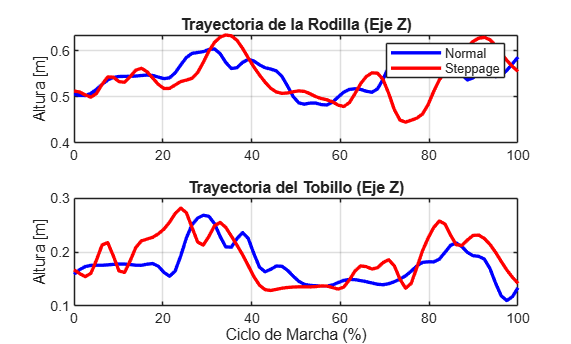

% saveas(fig1, 'Inclinacion_Pelvica_Comparativa.png');

%% 3. EXTRACCIÓN DE CARACTERÍSTICAS (FEATURE ENGINEERING)
dataMatrix = dataTable{:, 2:end}; 
originalNames = dataTable.Properties.VariableNames(2:end);
numVars = size(dataMatrix, 2);
extractedFeatures = zeros(1, numVars * 5);
newFeatureNames = cell(1, numVars * 5);

colIndex = 1;
for i = 1:numVars
    signal = dataMatrix(:, i);
    varName = originalNames{i};
    
    extractedFeatures(colIndex : colIndex+4) = [max(signal), min(signal), ...
        max(signal)-min(signal), mean(signal), std(signal)];
    
    newFeatureNames{colIndex} = [varName, '_Max'];
    newFeatureNames{colIndex+1} = [varName, '_Min'];
    newFeatureNames{colIndex+2} = [varName, '_ROM'];
    newFeatureNames{colIndex+3} = [varName, '_Mean'];
    newFeatureNames{colIndex+4} = [varName, '_Std'];
    colIndex = colIndex + 5;
end
featuresTable = array2table(extractedFeatures, 'VariableNames', newFeatureNames);
featuresTable.Clase = "Normal";

%% 4. ANÁLISIS CINEMÁTICO DE VARIABLES CRÍTICAS (KNEE & ANKLE)
% Filtraje de señales críticas (Eje Z)
[b4, a4] = butter(4, fc/(fs_objetivo/2));

knee_norm_f = filtfilt(b4, a4, dataTable.RightKnee_Z);
knee_step_f = filtfilt(b4, a4, datasteppageTable.RightKnee_Z(1:80));
ankle_norm_f = filtfilt(b4, a4, dataTable.RightAnkle_Z);
ankle_step_f = filtfilt(b4, a4, datasteppageTable.RightAnkle_Z(1:80));

% Normalización del Ciclo (0-100%)
t_norm_ciclo = linspace(0, 100, length(knee_norm_f));
t_step_ciclo = linspace(0, 100, length(knee_step_f));

% Gráfica 2: Trayectorias Rodilla y Tobillo
fig2 = figure('Name', 'Cinematica_Knee_Ankle', 'Color', 'w');
subplot(2, 1, 1);
plot(t_norm_ciclo, knee_norm_f, 'b', 'LineWidth', 2); hold on;
plot(t_step_ciclo, knee_step_f, 'r', 'LineWidth', 2);
title('Trayectoria de la Rodilla (Eje Z)');
ylabel('Altura [m]'); grid on; legend('Normal', 'Steppage');

subplot(2, 1, 2);
plot(t_norm_ciclo, ankle_norm_f, 'b', 'LineWidth', 2); hold on;
plot(t_step_ciclo, ankle_step_f, 'r', 'LineWidth', 2);
title('Trayectoria del Tobillo (Eje Z)');
xlabel('Ciclo de Marcha (%)'); ylabel('Altura [m]'); grid on;


% saveas(fig2, 'Trayectoria_Rodilla_Tobillo.png');

disp('Procesamiento completado. Figuras guardadas en la carpeta actual.');

Procesamiento completado. Figuras guardadas en la carpeta actual.


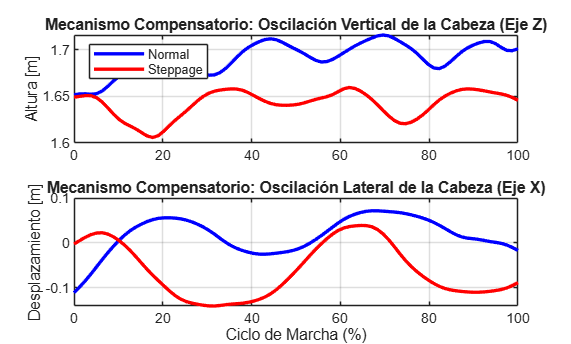

%% 5. ANÁLISIS DEL MECANISMO DE COMPENSACIÓN (CABEZA)
% Filtraje de las señales de la cabeza (Ejes Z y X) usando el mismo filtro
head_z_norm_f = filtfilt(b4, a4, dataTable.Head_Z);
head_z_step_f = filtfilt(b4, a4, datasteppageTable.Head_Z(1:80));

head_x_norm_f = filtfilt(b4, a4, dataTable.Head_X);
head_x_step_f = filtfilt(b4, a4, datasteppageTable.Head_X(1:80));

% Gráfica 3: Trayectorias de la Cabeza (Mecanismo Compensatorio)
fig3 = figure('Name', 'Cinematica_Cabeza_Compensacion', 'Color', 'w');

% Subplot 1: Oscilación Vertical (Eje Z) - Evalúa el rebote por falta de amortiguación
subplot(2, 1, 1);
plot(t_norm_ciclo, head_z_norm_f, 'b', 'LineWidth', 2); hold on;
plot(t_step_ciclo, head_z_step_f, 'r', 'LineWidth', 2);
title('Mecanismo Compensatorio: Oscilación Vertical de la Cabeza (Eje Z)');
ylabel('Altura [m]'); grid on; legend('Normal', 'Steppage', 'Location', 'best');

% Subplot 2: Oscilación Lateral (Eje X) - Evalúa el contrapeso postural del tronco
subplot(2, 1, 2);
plot(t_norm_ciclo, head_x_norm_f, 'b', 'LineWidth', 2); hold on;
plot(t_step_ciclo, head_x_step_f, 'r', 'LineWidth', 2);
title('Mecanismo Compensatorio: Oscilación Lateral de la Cabeza (Eje X)');
xlabel('Ciclo de Marcha (%)'); ylabel('Desplazamiento [m]'); grid on;

% Guardar la figura automáticamente
saveas(fig3, 'Trayectoria_Cabeza_Compensacion.png');